clear;clc

## 系统参数

m = 1.6; % 电磁吸振器器质量
M = 100; % 待减振对象质量
k_m = 2800; % 电磁吸振器刚度
k_M = 200000; % 平台刚度
k_f = 45; % 电—力常数 N/A 来自要求文件
k_E = 0; % 作动器反电动势系数 % 来自图片参数
L = 0.0045; % 线圈的电感 来自图片参数
R_m = 5; % 线圈的电阻 % 来自图片参数
c_m = 0.2; % 电磁吸振器阻尼
c_M = 1; % 平台阻尼
is_a = true; % 是否加速度反馈
w_m = sqrt(k_m/m); % 吸振器理想固有频率
w_M = sqrt(k_M/M); % 被控物体理想固有频率

num = 1;
den = [L R_m];
cf_system = tf(num,den); % 电流环传函

## 有控制的状态空间方程建立（位移和速度为状态量，输入取地基的位移）

Ac = [0      1       0           0;
    -k_m/m -c_m/m   k_m/m       c_m/m;
     0      0       0           1;
     k_m/M  c_m/M -(k_m+k_M)/M -(c_m+c_M)/M];
Bc = [0 +k_f/m 0 -k_f/M]';
Cc = [-k_m/m -c_m/m   k_m/m       c_m/m;
      k_m/M  c_m/M -(k_m+k_M)/M -(c_m+c_M)/M];
Dc = [+k_f/m -k_f/M]';
E_X = eye(4);
Ec = [0 0 0 1/M]';

msc_system = ss(Ac,Bc,Cc,Dc); % 二自由度系统建模
% LQR 尝试
Q = [0 0  0   0;
     0 0  0   0;
     0 0  1e3 0;
     0 0  0  1e5];
R = 1e3;
K = lqr(msc_system,Q,R)

K =     0.0000    0.5906 -355.6062   -3.7995


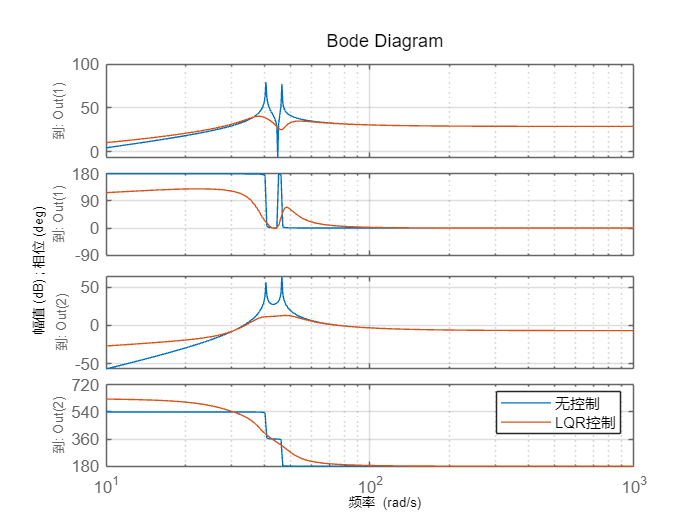

%% 新系统建立
lqr_system = ss(Ac-Bc*K,Bc,Cc,Dc);
%% 绘制系统伯德图
figure
bode(msc_system)
hold on
bode(lqr_system)
grid on
h = gcf; % 获取当前图形句柄
% 设置频率范围（以rad/s为单位）
set(h.Children(2:5), 'XLim', [10, 1000]); % 频率范围
legend('无控制', 'LQR控制')

## 无控制状态空间建立

An = [0 1;
    -k_M/M -c_M/M];
Bn = [0 0]';
Cn = [1 0];
Dn = 0;
En = [0 1/M]';

## PID控制器

amp = 1; % 振幅
fre = 44; % 频率
% PID参数
if is_a
    % 加速度反馈
    Kp = 50;    % 比例系数
    Ki = 60000;     % 积分系数
    Kd = 0.0006;     % 微分系数
else
    % 位移反馈
    Kp = 27000;    % 比例系数
    Ki = 13000;     % 积分系数
    Kd = 00070;     % 微分系数
end
sim("MS_Model.slx");

找不到系统或文件 'MS_Model.slx'。

## 绘图与初步分析

tf_m_system = tf(msc_system);
x_system = tf_m_system(2,1) % 输入电流到被控位移的传递函数
bode(x_system)
PID_control = pid(Kp,Ki,Kd);
all_system = PID_control * x_system * cf_system
bode(all_system)
fall_system = feedback(all_system, 1) % 闭环控制
bode(fall_system)